# MAE384 Group Project

Initialize common variables and functions:

% Beta is the Transmission Rate
% Gamma is the Recovery Rate
% S(t) is # of Susceptible Individuals at t
% I(t) is # of Infected Individuals at t
% R(t) is # of Recovered Individuals at t
dSdt = @(S,I,R,beta) (-beta./(S+I+R)).*S.*I;
dIdt = @(S,I,R,beta,gamma) (beta./(S+I+R)).*S.*I - gamma.*I;
dRdt = @(I,gamma) gamma.*I;

# Part 1. Runge-Kutta

## 1.

%Parameters
h1 = 1; %Time step; Days
t0 = 0; %Initial Time
s0 = 990; %Initial Susceptible Indiviudals
i0 = 10; %Initial Infected Individuals
r0 = 0; %Initial Recovered Individuals
T = 100; %Total Simulation Time, Days
betaFlu = 0.3;
gammaFlu = 0.1;
betaCovid = 1;
gammaCovid = 0.1;
betaMeas = 2;
gammaMeas = 0.2;

Flu = [0.3,0.1]; %Beta,Gamma
Covid = [1,0.1]; %Beta,Gamma
Meas = [2,0.2]; %Beta,Gamma
Dis = [Flu;Covid;Meas];


%Solving
t1 = 0; %Time variable part 1, days
N = (T - t0)/h1; %Number of Steps
S = zeros(3,N+1);
S(:,1) = s0;
I = zeros(3,N+1);
I(:,1) = i0;
R = zeros(3,N+1);
R(:,1) = r0;
for k = 1:3
    beta(k) = Dis(k,1);
    gamma(k) = Dis(k,2);
    for i = 1:N
        k1 = SIRModel(S(k,i),I(k,i),R(k,i),beta(k),gamma(k));
        k2 = SIRModel(S(k,i) + 0.5*h1*k1(1),I(k,i) + 0.5*h1*k1(2),R(k,i) + 0.5*h1*k1(3),beta(k),gamma(k));
        k3 = SIRModel(S(k,i) + 0.5*h1*k2(1),I(k,i) + 0.5*h1*k2(2),R(k,i) + 0.5*h1*k2(3),beta(k),gamma(k));
        k4 = SIRModel(S(k,i) + h1*k3(1),I(k,i) + h1*k3(2),R(k,i) + h1*k3(3),beta(k),gamma(k));
        S(k,i+1) = S(k,i) + (1/6)*(k1(1) + 2*k2(1) + 2*k3(1) + k4(1))*h1;
        I(k,i+1) = I(k,i) + (1/6)*(k1(2) + 2*k2(2) + 2*k3(2) + k4(2))*h1;
        R(k,i+1) = R(k,i) + (1/6)*(k1(3) +2*k2(3) + 2*k3(3) + k4(3))*h1;
    end
end
S

S =   990.0000  986.7233  982.7517  977.9476  972.1504  965.1750  956.8112  946.8242  934.9582  920.9421  904.5008  885.3697  863.3161  838.1646  809.8263  778.3272  743.8329  706.6633  667.2911  626.3229  584.4624  542.4589  501.0507  460.9116  422.6088  386.5764  353.1076  322.3608  294.3775  269.1053  246.4229  226.1627  208.1313  192.1241  177.9367  165.3732  154.2502  144.3999  135.6707  127.9274  121.0502  114.9337  109.4856  104.6251  100.2817   96.3943   92.9091   89.7797   86.9654   84.4306
  990.0000  974.2615  937.7322  859.0950  714.1869  510.0236  308.1596  165.6117   85.1558   44.1330   23.6723   13.2814    7.8142    4.8162    3.1012    2.0796    1.4474    1.0422    0.7741    0.5913    0.4633    0.3715    0.3042    0.2539    0.2155    0.1858    0.1625    0.1439    0.1290    0.1168    0.1067    0.0984    0.0914    0.0855    0.0805    0.0762    0.0725    0.0694    0.0666    0.0642    0.0621    0.0603    0.0587    0.0573    0.0560    0.0549    0.0539    0.0530    0.0522    0

I

I =    10.0000   12.1716   14.7988   17.9694   21.7848   26.3598   31.8225   38.3119   45.9741   54.9553   65.3919   77.3971   91.0425  106.3385  123.2119  141.4867  160.8708  180.9530  201.2159  221.0640  239.8666  257.0101  271.9500  284.2554  293.6385  299.9651  303.2483  303.6279  301.3417  296.6938  290.0250  281.6870  272.0232  261.3545  249.9707  238.1265  226.0399  213.8937  201.8376  189.9917  178.4497  167.2829  156.5435  146.2674  136.4776  127.1861  118.3963  110.1047  102.3027   94.9774
   10.0000   24.1358   56.8424  126.7160  253.1347  423.6110  575.0844  655.4489  669.2084  644.3231  602.3596  554.8685  507.2403  461.8089  419.4864  380.5351  344.9217  312.4822  283.0000  256.2424  231.9792  209.9906  190.0712  172.0314  155.6968  140.9085  127.5215  115.4039  104.4360   94.5092   85.5250   77.3941   70.0358   63.3766   57.3503   51.8967   46.9616   42.4956   38.4543   34.7971   31.4877   28.4930   25.7831   23.3309   21.1118   19.1038   17.2868   15.6426   14.1547   12

R

R =          0    1.1051    2.4495    4.0829    6.0648    8.4652   11.3663   14.8638   19.0677   24.1026   30.1073   37.2333   45.6414   55.4969   66.9618   80.1861   95.2963  112.3837  131.4930  152.6131  175.6709  200.5310  226.9993  254.8329  283.7528  313.4585  343.6441  374.0113  404.2808  434.2008  463.5522  492.1502  519.8454  546.5214  572.0925  596.5003  619.7098  641.7063  662.4916  682.0809  700.5001  717.7834  733.9710  749.1075  763.2407  776.4197  788.6946  800.1155  810.7319  820.5920
         0    1.6027    5.4254   14.1890   32.6785   66.3654  116.7560  178.9394  245.6358  311.5439  373.9680  431.8501  484.9454  533.3750  577.4124  617.3853  653.6309  686.4755  716.2259  743.1663  767.5575  789.6379  809.6246  827.7148  844.0876  858.9056  872.3160  884.4522  895.4351  905.3741  914.3683  922.5075  929.8729  936.5379  942.5692  948.0270  952.9659  957.4350  961.4791  965.1386  968.4501  971.4467  974.1582  976.6119  978.8322  980.8413  982.6593  984.3044  985.7930  987

## 2.

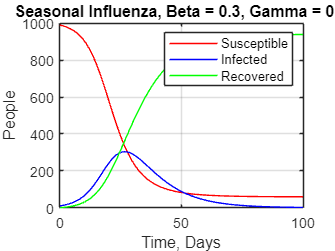

t = 0:100;
%Flu
plot(t,S(1,:),'r',t,I(1,:),'b',t,R(1,:),'g')
hold on;
grid on;
title('Seasonal Influenza, Beta = 0.3, Gamma = 0.1');
xlabel('Time, Days');
ylabel('People');
legend('Susceptible','Infected','Recovered');
hold off;

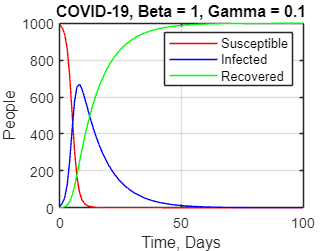


%Covid-19
plot(t,S(2,:),'r',t,I(2,:),'b',t,R(2,:),'g')
hold on;
grid on;
title('COVID-19, Beta = 1, Gamma = 0.1');
xlabel('Time, Days');
ylabel('People');
legend('Susceptible','Infected','Recovered');
hold off;

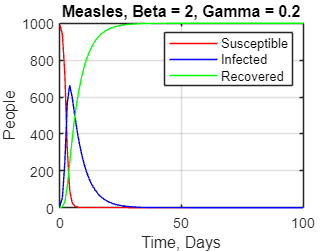


%Measles
plot(t,S(3,:),'r',t,I(3,:),'b',t,R(3,:),'g')
hold on;
grid on;
title('Measles, Beta = 2, Gamma = 0.2');
xlabel('Time, Days');
ylabel('People');
legend('Susceptible','Infected','Recovered');
hold off;

# Part 2: Interpolation

% Base case of Seasonal Influenza
beta = 0.3;
gamma = 0.1;
h2 = 2;
t = 0:100;

% linear
S2lin = zeros(1, N + 1);
S2lin(1, 1) = s0;
I2lin = zeros(1, N + 1);
I2lin(1, 1) = i0;
R2lin = zeros(1, N + 1);
R2lin(1, 1) = r0;
for i = 3:2:(N + 1)
    S2lin(i) = S(1, i);
    I2lin(i) = I(1, i);
    R2lin(i) = R(1, i);
end
for i = 2:2:(N + 1)
    S2lin(i) = S2lin(i - 1) + (S2lin(i + 1) - S2lin(i - 1)) / 2;
    I2lin(i) = I2lin(i - 1) + (I2lin(i + 1) - I2lin(i - 1)) / 2;
    R2lin(i) = R2lin(i - 1) + (R2lin(i + 1) - R2lin(i - 1)) / 2;
end

Nint = N / 2;
for k = 2:2:(N + 1)
    EL2Slin = sqrt(sum((S2lin(k) - S(1, k))^2) / Nint);
    EL2Ilin = sqrt(sum((I2lin(k) - I(1, k))^2) / Nint);
    EL2Rlin = sqrt(sum((R2lin(k) - R(1, k))^2) / Nint);
end

% quadratic
S2quad = zeros(1, N + 1);
S2quad(1, 1) = s0;
I2quad = zeros(1, N + 1);
I2quad(1, 1) = i0;
R2quad = zeros(1, N + 1);
R2quad(1, 1) = r0;
for i = 3:2:(N + 1)
    S2quad(i) = S(1, i);
    I2quad(i) = I(1, i);
    R2quad(i) = R(1, i);
end
for i = 2:2:(N + 1)
    if (i == 2)
        Sb0 = S2quad(i - 1);
        Sb1 = (S2quad(i + 1) - S2quad(i - 1)) / 2;
        Sb2 = (((S2quad(i + 3) - S2quad(i + 1)) / 2) - ((S2quad(i + 1) - S2quad(i - 1)) / 2)) / 4;
        S2quad(i) = Sb0 + Sb1 + (Sb2 * -1);
        Ib0 = I2quad(i - 1);
        Ib1 = (I2quad(i + 1) - I2quad(i - 1)) / 2;
        Ib2 = (((I2quad(i + 3) - I2quad(i + 1)) / 2) - ((I2quad(i + 1) - I2quad(i - 1)) / 2)) / 4;
        I2quad(i) = Ib0 + Ib1 + (Ib2 * -1);
        Rb0 = R2quad(i - 1);
        Rb1 = (R2quad(i + 1) - R2quad(i - 1)) / 2;
        Rb2 = (((R2quad(i + 3) - R2quad(i + 1)) / 2) - ((R2quad(i + 1) - R2quad(i - 1)) / 2)) / 4;
        R2quad(i) = Rb0 + Rb1 + (Rb2 * -1);
    else
        Sb0 = S2quad(i - 3);
        Sb1 = (S2quad(i - 1) - S2quad(i - 3)) / 2;
        Sb2 = (((S2quad(i + 1) - S2quad(i - 1)) / 2) - ((S2quad(i - 1) - S2quad(i - 3)) / 2)) / 4;
        S2quad(i) = Sb0 + (Sb1 * 3) + (Sb2 * 3);
        Ib0 = I2quad(i - 3);
        Ib1 = (I2quad(i - 1) - I2quad(i - 3)) / 2;
        Ib2 = (((I2quad(i + 1) - I2quad(i - 1)) / 2) - ((I2quad(i - 1) - I2quad(i - 3)) / 2)) / 4;
        I2quad(i) = Ib0 + (Ib1 * 3) + (Ib2 * 3);
        Rb0 = R2quad(i - 3);
        Rb1 = (R2quad(i - 1) - R2quad(i - 3)) / 2;
        Rb2 = (((R2quad(i + 1) - R2quad(i - 1)) / 2) - ((R2quad(i - 1) - R2quad(i - 3)) / 2)) / 4;
        R2quad(i) = Rb0 + (Rb1 * 3) + (Rb2 * 3);
    end
end

for k = 2:2:(N + 1)
    EL2Squad = sqrt(sum((S2quad(k) - S(1, k))^2) / Nint);
    EL2Iquad = sqrt(sum((I2quad(k) - I(1, k))^2) / Nint);
    EL2Rquad = sqrt(sum((R2quad(k) - R(1, k))^2) / Nint);
end

EL2 = [EL2Slin EL2Ilin EL2Rlin; EL2Squad EL2Iquad EL2Rquad];
% from looking at the EL2 matrix, it's clear that the quadratic
% interpolation provides smaller errors. for example, compare EL2 of the
% susceptible population for the linear and quadratic, and notice that the
% 2nd row (quadratic) is 0.0155 * 10^-3 which is smaller than the 1st row (linear),
% which is 0.1750 * 10^-3.

# Part 3: Least Squares Method

% Data for least Square / part 3
beta3 = 0.3; %real value for beta
gamma3 = 0.1; %real value for gamma
S3 = 990; %Initial susceptible population
I3 = 10; %Initial infected
R3 = 0; %Initial recovered
h = 1; 
T3 = 30;
t1 = 0;
t3 = 0:30

t3 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N3 = (T3-t1)/h; %number of step sizes
Np3 = 1000 %value given

Np3 = 1000

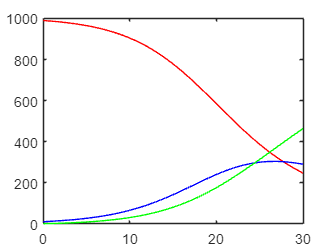

%kp3test = (beta3 * S3) / N3 - gamma3


%question 1
%finds "true" values
for l = 1:N3
        k1p3 = SIRModel(S3(l),I3(l),R3(l),beta3,gamma3);
        k2p3 = SIRModel(S3(l) + 0.5*h*k1p3(1),I3(l) + 0.5*h*k1p3(2),R3(l) + 0.5*h*k1p3(3),beta3,gamma3);
        k3p3 = SIRModel(S3(l) + 0.5*h*k2p3(1),I3(l) + 0.5*h*k2p3(2),R3(l) + 0.5*h*k2p3(3),beta3,gamma3);
        k4p3 = SIRModel(S3(l) + h*k3p3(1),I3(l) + h*k3p3(2),R3(l) + h*k3p3(3),beta3,gamma3);
        S3(l+1) = S3(l) + (1/6)*(k1p3(1) + 2*k2p3(1) + 2*k3p3(1) + k4p3(1))*h;
        I3(l+1) = I3(l) + (1/6)*(k1p3(2) + 2*k2p3(2) + 2*k3p3(2) + k4p3(2))*h;
        R3(l+1) = R3(l) + (1/6)*(k1p3(3) +2*k2p3(3) + 2*k3p3(3) + k4p3(3))*h;
end
plot(t3,S3(1,:),'r',t3,I3(1,:),'b',t3,R3(1,:),'g')


%question 2

[sumX,sumX2,sumXY,sumY] = leastSquareSums(N3,I3); %values of sums used in least squares method

kp3 = (N3*sumXY - sumX*sumY)/(N3*sumX2 - (sumX)^2) %estimate for k in question 2, this value is a1 in least squares

kp3 = 0.1233

I03 = exp((1/N3)*sumY - kp3*(1/N3)*sumX) %estimate for I0 in question 2, this value is a0

I03 = 14.0704

betaEst1 = (Np3*(kp3+gamma3))/(990) %estimate for beta in question 2

betaEst1 = 0.2255


%question 3
N10 = 10;
[sumXq3,sumX2q3,sumXYq3,sumYq3] = leastSquareSums(N10,I3);

kp3q3 = (N10*sumXYq3 - sumXq3*sumYq3)/(N10*sumX2q3 - (sumXq3)^2) %estimate for k in question 3, this value is a1

kp3q3 = 0.1897

I03q3 = exp((1/N10)*sumYq3 - kp3q3*(1/N10)*sumXq3) %estimate for I0 in question 3, this value is a0

I03q3 = 8.3690

betaEst2 = (Np3*(kp3q3+gamma3))/(990) %estimate for beta in question 3

betaEst2 = 0.2926

Part III, question 3:

The estimates of I(0) and Beta do improve when the step size is reduced from 30 to 10, this is due to the fact that we are using the value S as a constant at S(0) despite how the value of S(t) changes throughout the time. Due to this, the values calculated will be more accurate at earlies tims, with a much greater accuracy at time = 10 steps, making the less step sizes more accurate.

# Part 4: Fourier Analysis

% Parameters
beta0 = 0.3;  
A = 5;  
omega1 = 2*pi*365/365;  % daily variation  
omega2 = 2*pi*100/365;  % weekly variation  
gamma = 0.1;  
h = 0.1;  
T = 30;  
S0 = 990;  
I0 = 10;  
R0 = 0;  
  
% Part 2&6:
t = 0:h:T;   
beta1 = @(t) beta0*(1 + A*sin(omega1*t));  
beta2 = @(t) beta0*(1 + A*sin(omega2*t));  
S1 = zeros(size(t));  
I1 = zeros(size(t));  
R1 = zeros(size(t));  
S2 = zeros(size(t));  
I2 = zeros(size(t));  
R2 = zeros(size(t));  
% initial cond.
S1(1) = S0;  
I1(1) = I0;  
R1(1) = R0;  
S2(1) = S0;  
I2(1) = I0;  
R2(1) = R0;  
  
%SIR model    
for i = 2:length(t)  
   B1 = beta1(t(i));   
   B2 = beta2(t(i));  
   SIR1 = SIRModel(S1(i-1), I1(i-1), R1(i-1), B1, gamma);  
   SIR2 = SIRModel(S2(i-1), I2(i-1), R2(i-1), B2, gamma);  
   S1(i) = S1(i-1) + h*SIR1(1);  
   I1(i) = I1(i-1) + h*SIR1(2);  
   R1(i) = R1(i-1) + h*SIR1(3);  
   S2(i) = S2(i-1) + h*SIR2(1);  
   I2(i) = I2(i-1) + h*SIR2(2);   
   R2(i) = R2(i-1) + h*SIR2(3);  
end  
  
% Part 3&6:
% Plot for 2pi*100/365 
figure;  
plot(t, S1, 'b', t, I1, 'r', t, R1, 'g');  
xlabel('Time (days)');  
ylabel('Number of individuals');  
legend('Susceptible', 'Infected', 'Recovered');  
title('Daily variation (ω = 2π*365/365)');  
  
% Plot for 2pi*100/365
figure;  
plot(t, S2, 'b', t, I2, 'r', t, R2, 'g');  
xlabel('Time (days)');  
ylabel('Number of individuals');  
legend('Susceptible', 'Infected', 'Recovered');  
title('Weekly variation (ω = 2π*100/365)');  
  
% Part 4:Fast Fourier Transform 
I1_fft = fft(I1);  
I2_fft = fft(I2);  
  
% Part 5: Spectrum plot of Infected

f = 1/T*(0:length(I1_fft)/2);  
  
% Spectrum plot for 2pi*365/365
figure;  
plot(f(1:length(f)/2), abs(I1_fft(1:length(f)/2)));  
xlabel('Frequency (1/day)');  
ylabel('Absolute value of Fourier coefficients');  
title('Spectrum for daily variation (ω = 2π*365/365)');  
  
% Spectrum plot for 2pi*100/365 (to compare)
figure;  
plot(f(1:length(f)/2), abs(I2_fft(1:length(f)/2)));  
xlabel('Frequency (1/day)');  
ylabel('Absolute value of Fourier coefficients');  
title('Spectrum for weekly variation (ω = 2π*100/365)');

- For part 3 when we plot the signals of S(t), I(t), and R(t), we can see that there is in fact periodic fluctuations with both suspectible and infected

- When plotting the Spectrum of 2*pi*365/365 we can see it starts high then drops down and spikes a little around the frequency of 1. 

- When plotting for the weekly variation (2pi*100/365) we can see from the plot that our values shift to a higher frequency since it's collecting the information of infected,suspecitble, and recovered of the whole week. This would mean we would be seeing a bigger change throughout the whole plot if we were to go to 100 for our total time. 

function [sumX,sumX2,sumXY,sumY] = leastSquareSums(N3,I3) %function to find the sum of values used in least squares
sumX=0;
sumX2=0;
sumY=0;
sumXY=0;
    for b = 1:N3
    sumX = sumX + b;
    sumX2 = sumX2 + b^2;
    sumY = sumY + log(I3(b));
    sumXY = sumXY + b*log(I3(b));
    end
end
